# Tutorial 1

## Question 3

clear
% a)
x = 10:20

x =     10    11    12    13    14    15    16    17    18    19    20



% b)
y = 30:40

y =     30    31    32    33    34    35    36    37    38    39    40



% c)
z = x + y

z =     40    42    44    46    48    50    52    54    56    58    60



% d)
x .* y

ans =    300   341   384   429   476   525   576   629   684   741   800



% e)
a = x * y.' 

a = 5885


% f)
b = x.' * y

b =    300   310   320   330   340   350   360   370   380   390   400
   330   341   352   363   374   385   396   407   418   429   440
   360   372   384   396   408   420   432   444   456   468   480
   390   403   416   429   442   455   468   481   494   507   520
   420   434   448   462   476   490   504   518   532   546   560
   450   465   480   495   510   525   540   555   570   585   600
   480   496   512   528   544   560   576   592   608   624   640
   510   527   544   561   578   595   612   629   646   663   680
   540   558   576   594   612   630   648   666   684   702   720
   570   589   608   627   646   665   684   703   722   741   760



% g)
size(a)

ans =      1     1


size(b)

ans =     11    11


## Question 4

clear
x = [2 5 1 6]

x =      2     5     1     6



% a)
sqrt(x)

ans =     1.4142    2.2361    1.0000    2.4495


x .^ (1/2)

ans =     1.4142    2.2361    1.0000    2.4495



% b)
y = mod(1:size(x, 2), 2) .* x .* 1j + ~mod(1:size(x, 2), 2) .* x;

y =    0.0000 + 2.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i



% c)
z = x + y

z =    2.0000 + 2.0000i   5.0000 + 0.0000i   1.0000 + 1.0000i   6.0000 + 0.0000i


real(z)

ans =      2     5     1     6


imag(z)

ans =      2     0     1     0



% d)
abs(z)

ans =     2.8284    5.0000    1.4142    6.0000


## Question 5

clear
t0 = 0;
T = 1;
samples = 1000;
t = linspace(t0, t0 + T, samples + 1);
t(end) = []

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490



% a)
y1 = log(2 + t + t.^2)

y1 =     0.6931    0.6936    0.6941    0.6947    0.6952    0.6957    0.6962    0.6967    0.6972    0.6977    0.6982    0.6987    0.6992    0.6997    0.7002    0.7007    0.7012    0.7018    0.7023    0.7028    0.7033    0.7038    0.7043    0.7048    0.7054    0.7059    0.7064    0.7069    0.7074    0.7080    0.7085    0.7090    0.7095    0.7100    0.7106    0.7111    0.7116    0.7121    0.7127    0.7132    0.7137    0.7143    0.7148    0.7153    0.7159    0.7164    0.7169    0.7175    0.7180    0.7185



% b)
y2 = exp(t) .* (1 + cos(3 * t))

y2 =     2.0000    2.0020    2.0040    2.0060    2.0079    2.0099    2.0119    2.0138    2.0158    2.0177    2.0196    2.0216    2.0235    2.0254    2.0273    2.0292    2.0311    2.0330    2.0348    2.0367    2.0386    2.0404    2.0423    2.0441    2.0459    2.0477    2.0496    2.0514    2.0532    2.0550    2.0567    2.0585    2.0603    2.0620    2.0638    2.0655    2.0673    2.0690    2.0707    2.0724    2.0741    2.0758    2.0775    2.0792    2.0809    2.0825    2.0842    2.0858    2.0875    2.0891



% c)
y3 = cos(t).^2 + sin(t).^2

y3 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


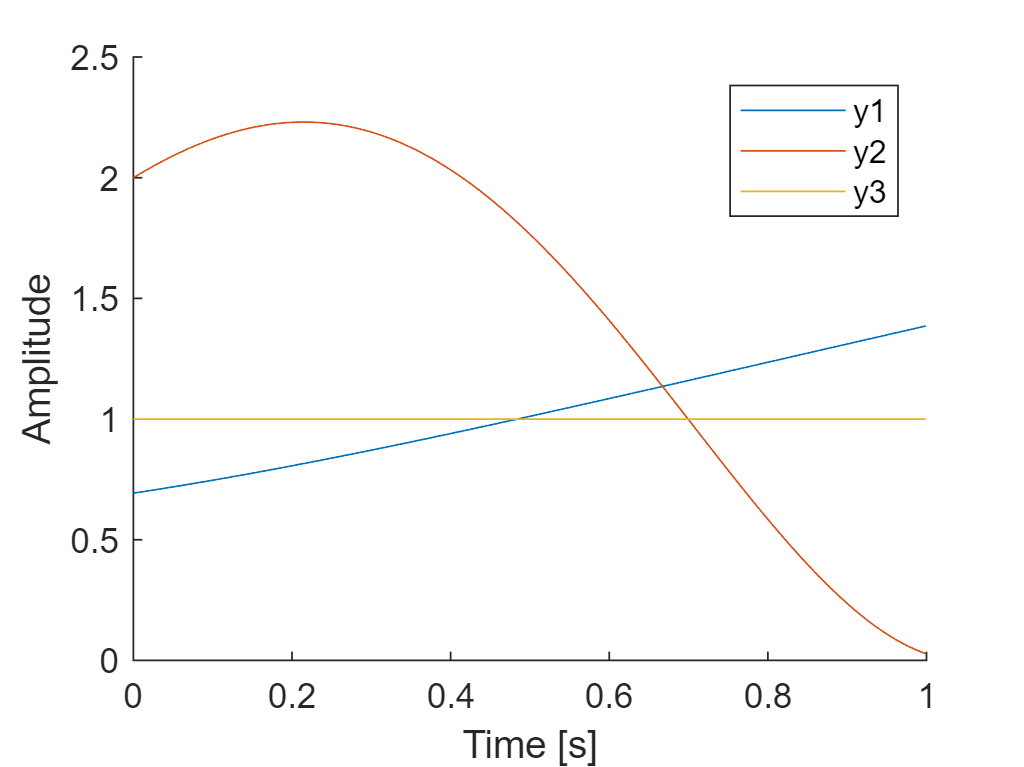


figure, hold on 
plot(t, y1)
plot(t, y2)
plot(t, y3)

xlabel("Time [s]")
ylabel("Amplitude")
legend('y1', 'y2', 'y3')

hold off